## Part 1

syms z
sol = tf('s')

sol =
 
  s
 
Continuous-time transfer function.



A1 = [[0 1 0];[1886.54 0 25017.31];[0 0 -86.956]];
A2 = [[0 1 0];[1886.54 0 -25017.31];[0 0 -86.956]];
B = [0;0;8.696];
C = [1 0 0];
G1 = C*inv((sol*eye(3)-A1))*B

G1 =
 
               2.176e05
  ----------------------------------
  s^3 + 86.96 s^2 - 1887 s - 1.64e05
 
Continuous-time transfer function.



G2 = C*inv((sol*eye(3)-A2))*B

G2 =
 
              -2.176e05
  ----------------------------------
  s^3 + 86.96 s^2 - 1887 s - 1.64e05
 
Continuous-time transfer function.



## Part 3

z = tf('z')

z =
 
  z
 
Sample time: unspecified
Discrete-time transfer function.



T1 = 0.0001;
T2 = 0.001;
T3 = 0.0005;
N=29345.71;
Kp=6.9355;
Ki=13.927;
Kd=0.328;

m1 = 2*(z-1)/(T1*(z+1));
Gdz1 = Kp + Ki/m1 + Kd*N/(1+N/m1)

Gdz1 =
 
  3.857e04 z^2 - 7.706e04 z + 3.849e04
  ------------------------------------
        9.869 z^2 - 8 z - 1.869
 
Sample time: unspecified
Discrete-time transfer function.




m2 = 2*(z-1)/(T2*(z+1));
Gdz2 = Kp + Ki/m2 + Kd*N/(1+N/m2)

Gdz2 =
 
  3.894e04 z^2 - 7.706e04 z + 3.812e04
  ------------------------------------
        62.69 z^2 - 8 z - 54.69
 
Sample time: unspecified
Discrete-time transfer function.




m3 = 2*(z-1)/(T3*(z+1));
Gdz3 = Kp + Ki/m3 + Kd*N/(1+N/m3)

Gdz3 =
 
  3.873e04 z^2 - 7.706e04 z + 3.833e04
  ------------------------------------
        33.35 z^2 - 8 z - 25.35
 
Sample time: unspecified
Discrete-time transfer function.



Mp = -(Ki+Kp*N)/(2*(N*Kd+Kp))+i*(((Ki+Kp*N)/(2*(N*Kd+Kp)))^2-Ki*N/(N*Kd+Kp))^0.5

Mp = -10.5655 + 8.3187i

Mn = -(Ki+Kp*N)/(2*(N*Kd+Kp))-i*(((Ki+Kp*N)/(2*(N*Kd+Kp)))^2-Ki*N/(N*Kd+Kp))^0.5

Mn = -10.5655 - 8.3187i


Gdzp1 = 1000*(z-exp(T1*Mp))*(z-exp(T1*Mn))/((z-1)*(z-exp(-N*T1)))

Gdzp1 =
 
  1000 z^2 - 1998 z + 997.9
  -------------------------
   z^2 - 1.053 z + 0.05315
 
Sample time: unspecified
Discrete-time transfer function.



Gdzp2 = 1000*(z-exp(T2*Mp))*(z-exp(T2*Mn))/((z-1)*(z-exp(-N*T2)))

Gdzp2 =
 
  1000 z^2 - 1979 z + 979.1
  -------------------------
      z^2 - z + 1.8e-13
 
Sample time: unspecified
Discrete-time transfer function.



Gdzp3 = 1000*(z-exp(T3*Mp))*(z-exp(T3*Mn))/((z-1)*(z-exp(-N*T3)))

Gdzp3 =
 
  1000 z^2 - 1989 z + (989.5-8.882e-16i)
  --------------------------------------
           z^2 - z + 4.243e-07
 
Sample time: unspecified
Discrete-time transfer function.



## Part 4

Hc=tf([217600],[1, 86.96, -1887, -164000]);
Gz=c2d(Hc,T1, 'zoh')

Gz =
 
  3.619e-08 z^2 + 1.444e-07 z + 3.603e-08
  ---------------------------------------
    z^3 - 2.991 z^2 + 2.983 z - 0.9913
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



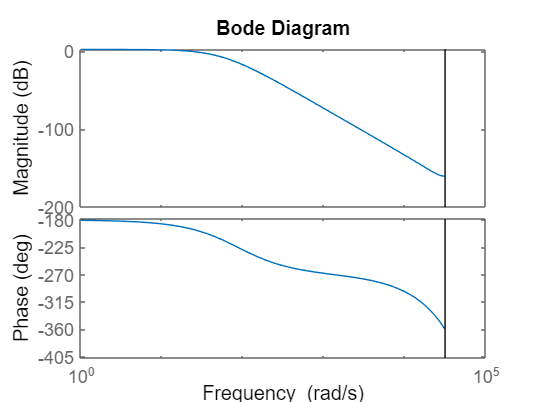

bode(Gz)

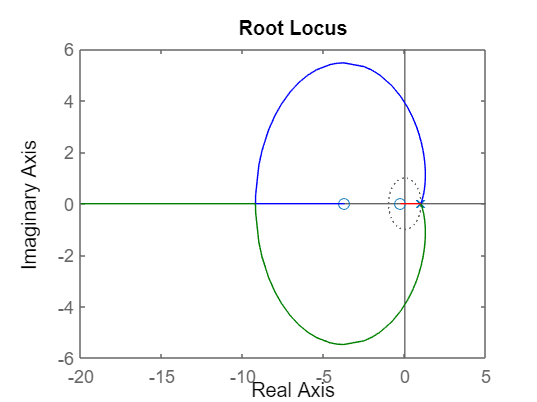

k =1;
rlocus(k*Gz)

[Gm, Pm, Wcg, Wcp] = margin(Gz);


% Bandwidth
[mag, phase, w] = bode(Gz);
mag = squeeze(mag);
phase = squeeze(phase);
idx = find(mag <= 1/sqrt(2), 1, 'first');  % 
bandwidth = w(idx);

disp('Gain Margin (dB):');

Gain Margin (dB):


disp(20*log10(Gm));  % converting to db

   -2.4563



disp('Phase Margin (degrees):');

Phase Margin (degrees):


disp(Pm);

  -14.9352



disp('Gain Crossover Frequency (rad/s):');

Gain Crossover Frequency (rad/s):


disp(Wcg);

     0



disp('Phase Crossover Frequency (rad/s):');

Phase Crossover Frequency (rad/s):


disp(Wcp);

   23.0778



disp('Bandwidth (rad/s):');

Bandwidth (rad/s):


disp(bandwidth);

   42.4750



## Part 6

P = 11.3216587748334;
I = 29.7415043652461;
D = 0.957335288291549;
N = 14403.0185628453;
Gcz = P + I*T1/(z-1) + D*N/(1+N*T1/(z-1))

Gcz =
 
  1.38e04 z^2 - 2.758e04 z + 1.378e04
  -----------------------------------
        z^2 - 0.5597 z - 0.4403
 
Sample time: unspecified
Discrete-time transfer function.



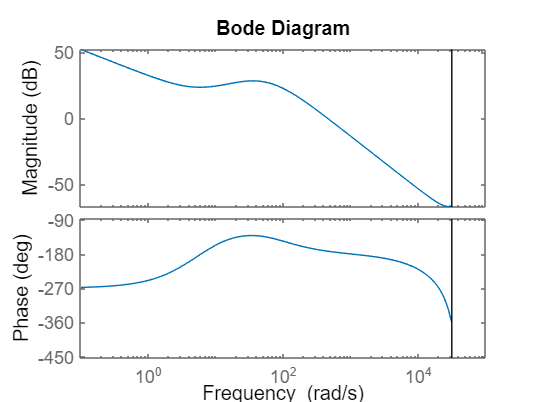

bode(Gcz*Gz)

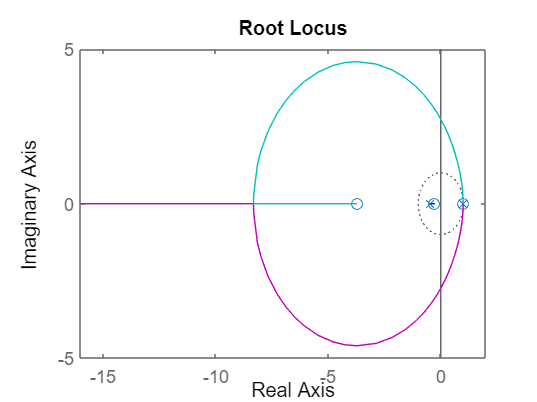

rlocus(Gcz*Gz)


[Gm, Pm, Wcg, Wcp] = margin(Gcz*Gz);

% Bandwidth
[mag, phase, w] = bode(Gcz*Gz);
mag = squeeze(mag);
phase = squeeze(phase);
idx = find(mag <= 1/sqrt(2), 1, 'first');  % 
bandwidth = w(idx);

disp('Gain Margin (dB):');

Gain Margin (dB):


disp(20*log10(Gm));  % converting to db

   14.3288



disp('Phase Margin (degrees):');

Phase Margin (degrees):


disp(Pm);

    7.6355



disp('Gain Crossover Frequency (rad/s):');

Gain Crossover Frequency (rad/s):


disp(Wcg);

   1.0389e+03



disp('Phase Crossover Frequency (rad/s):');

Phase Crossover Frequency (rad/s):


disp(Wcp);

  450.2725



disp('Bandwidth (rad/s):');

Bandwidth (rad/s):


disp(bandwidth);

  619.4085



% Analyze the root locus to find the range of K for stability
% Get the root locus data
[r, k] = rlocus(Gcz*Gz);

% Initialize the stability range
k_stable_min = inf;
k_stable_max = -inf;

% Loop over the gains to find where all poles are inside the unit circle
for i = 1:length(k)
    poles = r(:, i);
    if all(abs(poles) < 1)
        k_stable_min = min(k_stable_min, k(i));
        k_stable_max = max(k_stable_max, k(i));
    end
end

% Display the stable gain range
disp('Stable gain range:');

Stable gain range:


disp(['K_min = ', num2str(k_stable_min)]);

K_min = 0.19605


disp(['K_max = ', num2str(k_stable_max)]);

K_max = 5.0834


## Part 7

syms f_1 f_2 f_3 f_4 u_0 u_1 u_2 u_3
zs = zero(Gz)

zs =    -3.7240
   -0.2674


ps = pole(Gz)

ps =     1.0044
    0.9957
    0.9913


% eq1 = f1+f2+f3 == 1;
% eq2 = -f3 == 2.079*(-f2-2.079*(-f1-2.079)-1.074)+1.074*(-f1-2.079);
% eq3 = f3+(3.72^2)*f1 == 3.72*f2;
% [sol] = solve([eq1, eq2, eq3], [f1, f2, f3])
eq1 = f_1+f_2+f_3+f_4 == 1;
eq2 = f_4 == 3.72*(f_3-3.72*(f_2-3.72*f_1));
eq3 = f_4 == 1.0044*(-f_3+1.0044*(-f_2+1.0044*(-f_1+1.0044)));
eq4 = 3.619*10^(-8)*u_0 == f_1;
eq5 = 1.082*10^(-7)*u_0+3.619*10^(-8)*u_1 == f_2-2.991*f_1;
eq6 = -1.0837*10^(-7)*u_0+1.082*10^(-7)*u_1+3.619*10^(-8)*u_2 == f_3-2.991*f_2+2.983*f_1;
%eq7 = -1.0837*10^(-7)*u_1+1.082*10^(-7)*u_2+3.619*10^(-8)*u_3-3.603*10^(-8)*u_0 == f_4-2.991*f_3+2.983*f_2-0.9913*f_1;
eq8 = -3.603*10^(-8)*u_1-1.0837*10^(-7)*u_2+1.082*10^(-7)*u_3 == -2.991*f_4+2.983*f_3-0.9913*f_2;
eq9 = -3.603*10^(-8)*u_2-1.0837*10^(-7)*u_3 == 2.983*f_4-0.9913*f_3;
eq10 = -3.603*10^(-8)*u_3 == -0.9913*f_4;

[sol] = solve([eq1, eq2, eq3, eq4, eq6, eq5, eq9, eq10], [f_1, f_2, f_3, f_4, u_0, u_1, u_2, u_3])

sol = struct with fields:
    f_1: 23475521948845200099840821476714810368746063228982092350804533746100166919021789/46654351844789714102915583573889751577416644999220130881799427206183296628903750
    f_2: 15588927634893815204234441727632399220336186242518580712486416220034853346808490741/9330870368957942820583116714777950315483328999844026176359885441236659325780750000
    f_3: -651940513736643827245757159313500530935775037122766791038511112181499469811929329/777572530746495235048593059564829192956944083320335514696657120103054943815062500
    f_4: -1043291830288395492223467798811801535790923147665923837941768060613411255696315531/3110290122985980940194372238259316771827776333281342058786628480412219775260250000
    u_0: 324337136624001090589750836581363054626432866406819483911273360914632455383907750117376/23327175922394857051457791786944875788708322499610065440899713603091648314451875
    u_1: -35954455846435912404420188267610683465145761649247404485612472243728451404660138211016704

z = tf('z', T1)

z =
 
  z
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



%     f1= 95735691767/120490567000
%     f2= 893527325332/376533021875
%     f3= -6529346721831/3012264175000
%     F = (f1*z^2+f2*z+f3)/z^3; 

    f_1= 23475521948845200099840821476714810368746063228982092350804533746100166919021789/46654351844789714102915583573889751577416644999220130881799427206183296628903750

f_1 = 0.5032

    f_2= 15588927634893815204234441727632399220336186242518580712486416220034853346808490741/9330870368957942820583116714777950315483328999844026176359885441236659325780750000

f_2 = 1.6707

    f_3= -651940513736643827245757159313500530935775037122766791038511112181499469811929329/777572530746495235048593059564829192956944083320335514696657120103054943815062500

f_3 = -0.8384

    f_4= -1043291830288395492223467798811801535790923147665923837941768060613411255696315531/3110290122985980940194372238259316771827776333281342058786628480412219775260250000

f_4 = -0.3354

 F = (f_1*z^3+f_2*z^2+f_3*z+f_4)/z^4;

Gcdb = F/((1-F)*Gz)

Gcdb =
 
              0.5032 z^10 + 0.1655 z^9 - 4.335 z^8 + 6.657 z^7 - 3.154 z^6 - 0.1693 z^5 + 0.3325 z^4
  --------------------------------------------------------------------------------------------------------------
  3.619e-08 z^10 + 1.262e-07 z^9 - 9.711e-08 z^8 - 2.291e-07 z^7 + 7.304e-08 z^6 + 7.866e-08 z^5 + 1.209e-08 z^4
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



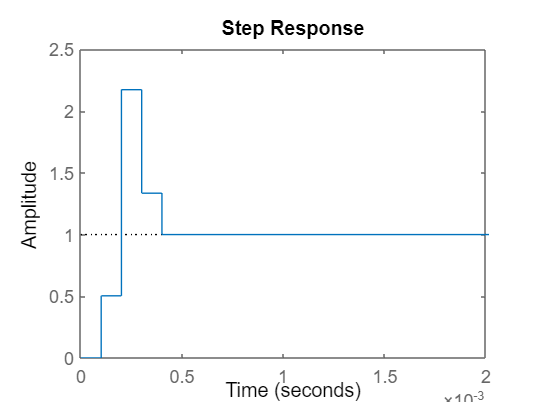


step(F);

## Part 9

% Discrete-time matrices
sysd = c2d(G1 , T1) 

sysd =
 
  3.618e-08 z^2 + 1.444e-07 z + 3.602e-08
  ---------------------------------------
    z^3 - 2.991 z^2 + 2.983 z - 0.9913
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



[A_d,B_d,C_d,D_d] = tf2ss(sysd.Numerator{1,1}, sysd.Denominator{1,1})

A_d =     2.9914   -2.9827    0.9913
    1.0000         0         0
         0    1.0000         0


B_d =      1
     0
     0


C_d = 	1.0e+-6 *

    0.0362    0.1444    0.0360


D_d = 0


Controllability = ctrb(A_d, B_d)

Controllability =     1.0000    2.9914    5.9655
         0    1.0000    2.9914
         0         0    1.0000


rank(Controllability)

ans = 3

Observability = obsv(A_d, C)

Observability =     1.0000         0         0
    2.9914   -2.9827    0.9913
    5.9655   -7.9310    2.9655


rank(Observability)

ans = 3

## Part 10

k = place(A_d, B_d, [0.01 0.001 0])

k =     2.9804   -2.9827    0.9913


## **Part 11**

%%Ackerman


a = poly(A_d);
a = a(2:end); % Remove the leading coefficient which is always 1


G_observer = A_d.';
H_observer = C_d.';


cpc = poly(G_observer);


desired_poles = [-0.6, 0.5, -0.1]; 
desired_poly = poly(desired_poles); 

% Remove the leading coefficient which is always 1
desired_coeffs = desired_poly(2:end);


phi = [1, a(1), a(2); 
       0, 1, a(1); 
       0, 0, 1];
phi_inv = inv(phi);

controllability_matrix = [H_observer, G_observer*H_observer, (G_observer^2)*H_observer];
controllInv = inv(controllability_matrix);


poles = cpc(2:end); % Remove the leading coefficient which is always 1
kl = (desired_coeffs - poles) * phi_inv * controllInv;
L = kl.';

disp('Observer Gain L:');

Observer Gain L:


disp(L);

   1.0e+07 *

    2.8296
    1.4062
    0.3803

